clc
clear
close all

## Step 1: Import Experimental Measurements, Identified Model and Model Parameters

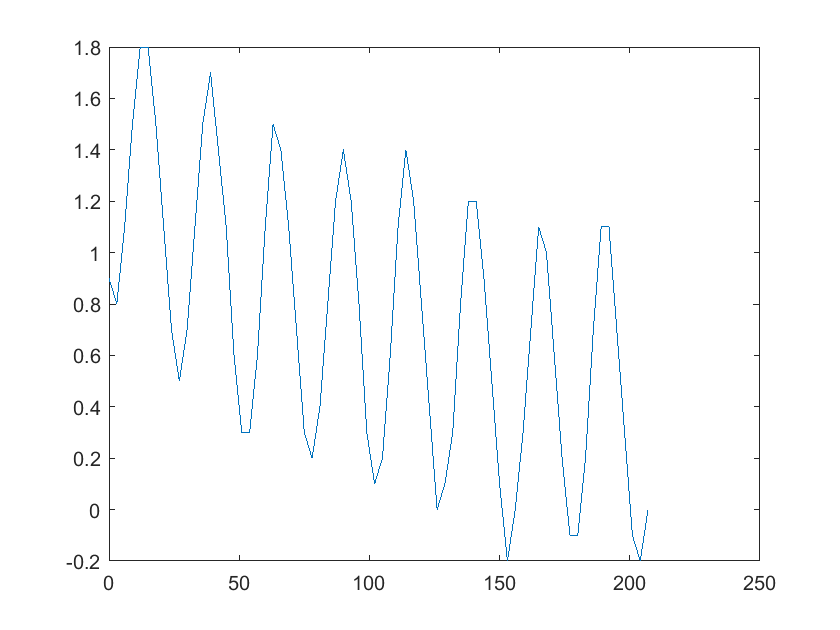

load ('plantoutput.mat')
load ('plantparameters.mat')
load('plantmodel.mat')
plot(Time,Temp)

## Step 2: Set up the Door-Opening Subsystem

M_times=[0 0;readmatrix('Input Files/SensorFeed.xlsx','Sheet',"DoorOpen")];
M_times(isnan(M_times))=0;
time_open=M_times(:,1)';
time_close=M_times(:,2)';


### Setting up Simulink Blocks **(Do not modify this section)**

initTemp_deg=Temp(1);

% Convert the experimental temperature array to a structure without time to
% enable cyclic repetition of the signal in simulink

Tamb1.time=[ ];
Tamb1.signals.values=Temp;
Tamb1.signals.dimensions=1;


Internal parameters for the Mass Transfer Subsystem

N=length(time_close);
Np1=N+1;
Nm1=N-1;
Tss=0.03;

## Step 3: Running the Model

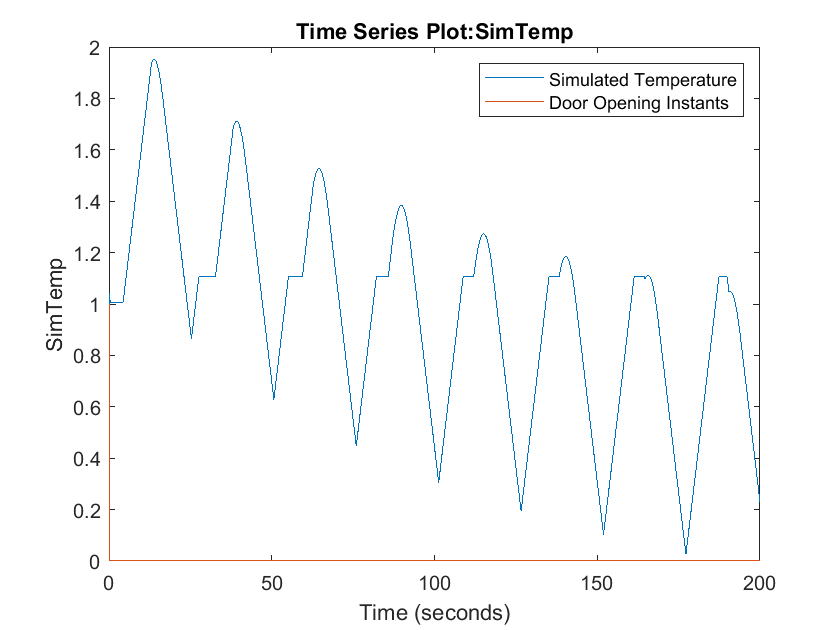

% Set the simulation time
SimTime=readmatrix('Input Files/SysIDSetupData.xlsx','Sheet',"Parameters","Range",'C11:C11'); % Minutes

% Run the model
yout=sim("ControlSys_v17_Demo.slx");
simulatedTemp=yout.logsout{3};
doorOpening=yout.logsout{2};
expTemp=yout.logsout{1};

% Plotting

plot(simulatedTemp.Values)
hold on
%plot(expTemp.Values)
plot(doorOpening.Values)
hold off
legend('Simulated Temperature','Door Opening Instants')

% Saving predicted temperature timeseries
save('PredictionOutput.mat','simulatedTemp')